clc
clear
close all

defines

load s20/data120.mat
s = tf('s');

Posunutie dat na 0 0

indx = 55;
t = t(indx:end) - t(indx);
y = y(indx:end) - y(indx);
figure(1)
hold on
plot(t,y)

Prva metoda

ind1 = find_t(y,0.7); 
ind2 = find_t(y,0.33);

t1 = t(ind1);
t2 = t(ind2);

K = y(end);
T = 0.794*(t1-t2);
D = 1.937*t2-0.937*t1;

if(D >= 0)
    F = (K/(1+T*s)^2)*exp(-D*s);
else
    F = (K/(1+T*s)^2);
end
t_model = linspace(0, t(end), 10000);
y_model = step(F,t_model);
plot(t_model,y_model)

Druha metoda

Tu = 0.043842;
Tn = 0.6901358; %odcitane z grafu

f1 = Tn/Tu;
k = map_fun(0.1,0.2,13.974,20.088,f1);
f2 = map_fun(1.292,1.495,0.1,0.2,k);

K = y(end);
T1 = Tn/f2;
T2 = k*T1;

F = K/((T1*s+1)*(T2*s+1))

F =
 
            4.348
  --------------------------
  0.03365 s^2 + 0.5768 s + 1
 
Continuous-time transfer function.
Model Properties


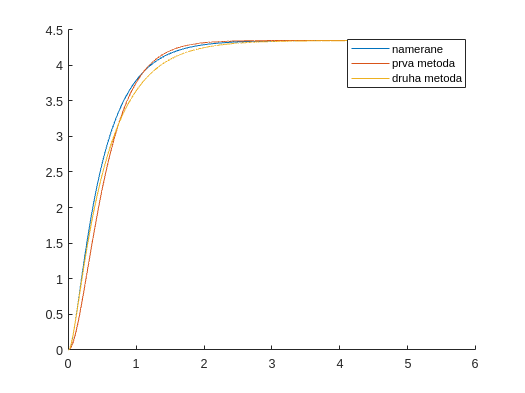


t_model = linspace(0, t(end), 10000);
y_model = step(F,t_model);
plot(t_model,y_model)
legend("namerane","prva metoda","druha metoda")